addpath("toolbox")

mutations = 96

mutations = 96

k = 5;  % Number of components in the dictionary
%https://doi.org/10.1093/bioinformatics/btw572
dir = 'C:\Files\github\Mutational_Signatures\'

dir = 'C:\Files\github\Mutational_Signatures\'

files = ["simulated_data/experiment_noise_1/data_v1_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v2_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v3_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v4_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v5_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v6_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v7_GRCh37_4_6_7a_9_18.csv"]

files = 1×7 string array
    "simulated_data/experiment_noise_1/data_v1_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v2_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v3_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v4_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v5_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v6_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v7_GRCh37_4_6_7a_9_18.csv"


disp(files(1))

simulated_data/experiment_noise_1/data_v1_GRCh37_4_6_7a_9_18.csv


data_table = readtable(strcat(dir, files(1)), ReadRowNames=true, ReadVariableNames=true);



disp(data_table)

                x0     x1      x2     x3     x4      x5     x6      x7      x8     x9     x10    x11    x12    x13    x14     x15     x16     x17     x18     x19    x20     x21    x22     x23    x24    x25     x26     x27    x28     x29    x30    x31    x32    x33     x34    x35    x36     x37    x38     x39    

data = table2array(data_table)

data =          442          12          53         284         321        1474          97         513         458          14         211          25         133         509         451        1335          41          64         293          79        2359         216        1245          92          49         402         647         214         997          51         110         114          40         765          40          32        1442          89         305         216          66         163          87          14         473         378          52        2100        1034         136
         515          18          64         187         268        1004         120         328         470          25         139          17          95         313         363         760          58          52         252          40         990         173         653          34          52         297         393         207         811          88          74         113        

% Normalize each column to sum to 1
data = bsxfun(@rdivide, data, sum(data));

# Perform methods

[M, x] = generate_cost_matrix_M(mutations)

M =          0    0.0357    0.0714    0.1071    0.1429    0.1786    0.2143    0.2500    0.2857    0.3214    0.3571    0.3929    0.4286    0.4643    0.5000    0.5357    0.5714    0.6071    0.6429    0.6786    0.7143    0.7500    0.7857    0.8214    0.8571    0.8929    0.9286    0.9643    1.0000    1.0357    1.0714    1.1071    1.1429    1.1786    1.2143    1.2500    1.2857    1.3214    1.3571    1.3929    1.4286    1.4643    1.5000    1.5357    1.5714    1.6071    1.6429    1.6786    1.7143    1.7500
    0.0357         0    0.0357    0.0714    0.1071    0.1429    0.1786    0.2143    0.2500    0.2857    0.3214    0.3571    0.3929    0.4286    0.4643    0.5000    0.5357    0.5714    0.6071    0.6429    0.6786    0.7143    0.7500    0.7857    0.8214    0.8571    0.8929    0.9286    0.9643    1.0000    1.0357    1.0714    1.1071    1.1429    1.1786    1.2143    1.2500    1.2857    1.3214    1.3571    1.3929    1.4286    1.4643    1.5000    1.5357    1.5714    1.6071    1.6429    1.6786    1

x =          0    0.0105    0.0211    0.0316    0.0421    0.0526    0.0632    0.0737    0.0842    0.0947    0.1053    0.1158    0.1263    0.1368    0.1474    0.1579    0.1684    0.1789    0.1895    0.2000    0.2105    0.2211    0.2316    0.2421    0.2526    0.2632    0.2737    0.2842    0.2947    0.3053    0.3158    0.3263    0.3368    0.3474    0.3579    0.3684    0.3789    0.3895    0.4000    0.4105    0.4211    0.4316    0.4421    0.4526    0.4632    0.4737    0.4842    0.4947    0.5053    0.5158


[D, lambda, objectives] = perform_WDL(data, M, k)

Size of data: [96 50]
Size of M: [96 96]
Optimize with respect to lambda
	Dual iteration : 0 Objective : 12.679118, Current step size 1.000000
		Gradnorm=0.638314 stop=0.000500
	Dual iteration : 1 Objective : 12.424435, Current step size 1.000000
		Gradnorm=0.536196 tol=0.000750
	Dual iteration : 21 Objective : 9.531424, Current step size 0.150060
		Gradnorm=0.113725 tol=0.007700
	Dual iteration : 41 Objective : 8.453942, Current step size 0.234469
		Gradnorm=0.122761 tol=0.015521
	Dual iteration : 61 Objective : 8.270334, Current step size 0.049172
		Gradnorm=0.034873 tol=0.018886
	Dual iteration : 69 Objective : 8.258613, Current step size 0.043980
		Gradnorm=0.019412 stop=0.019507
Optimize with respect to D
	Dual iteration : 0 Objective : 6.914103, Current step size 1.000000
		Gradnorm=0.619325 stop=0.000050
	Dual iteration : 1 Objective : 6.808606, Current step size 0.409600
		Gradnorm=0.457238 tol=0.000060
	Dual iteration : 21 Objective : 5.736789, Current step size 0.068719
		Gra

D =     0.0257    0.0001    0.0377    0.0006    0.0012
    0.0250    0.0002    0.0294    0.0008    0.0015
    0.0214    0.0003    0.0212    0.0011    0.0018
    0.0222    0.0006    0.0205    0.0017    0.0030
    0.0178    0.0009    0.0143    0.0023    0.0041
    0.0142    0.0014    0.0105    0.0029    0.0063
    0.0120    0.0021    0.0081    0.0030    0.0103
    0.0111    0.0032    0.0069    0.0033    0.0187
    0.0108    0.0040    0.0061    0.0036    0.0349
    0.0087    0.0040    0.0046    0.0049    0.0367


lambda =     0.1377    0.1227    0.1123    0.2053    0.3786    0.2012    0.1326    0.1461    0.1897    0.1605    0.2049    0.2127    0.1876    0.2063    0.1638    0.1319    0.0966    0.0981    0.2716    0.1222    0.1433    0.1934    0.1504    0.1157    0.1284    0.1940    0.1307    0.2227    0.3771    0.1219    0.1840    0.1406    0.1990    0.1452    0.1258    0.2084    0.1124    0.1219    0.1834    0.2088    0.1154    0.1075    0.1237    0.1050    0.1015    0.2420    0.1518    0.3731    0.2944    0.1294
    0.1869    0.4385    0.2017    0.1114    0.1205    0.1187    0.4234    0.2189    0.3550    0.2838    0.1288    0.1953    0.2015    0.1238    0.2074    0.2909    0.1097    0.1035    0.1226    0.3470    0.1409    0.1824    0.1181    0.1305    0.4309    0.1983    0.3170    0.3207    0.1234    0.4326    0.1980    0.2793    0.2250    0.1183    0.2916    0.3152    0.1260    0.2973    0.1035    0.2761    0.2908    0.1222    0.1746    0.1079    0.1099    0.1133    0.2208    0.1251    0.1218

objectives =   -10.4480  -12.4825  -13.1539  -13.4874  -13.6187  -13.6582  -13.6832  -13.6976  -13.7173  -13.7334  -13.7497  -13.7544  -13.7604  -13.7618


lineWidth, fontSize, YtickStep = visualize_data(data, x, fontSize, YtickStep)

lineWidth = 4

fontSize = 30

Error using perform_WasserSteinNMF>visualize_data
Too many input arguments.

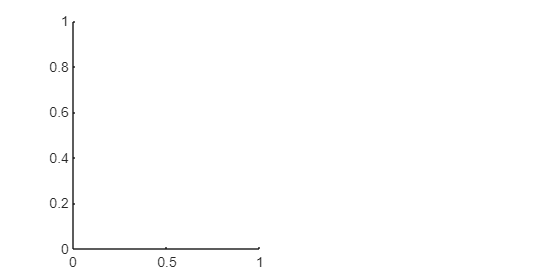

Not enough input arguments.

Error in perform_WasserSteinNMF>compare_data_and_reconstruction (line 81)
    plotDictionary(x, data(:, i), axisValues, lineWidth, fontSize, YtickStep, 0, 'x', 'Data');

compare_data_and_reconstruction(data, D, lambda, x, lineWidth)

visualize_D_and_lambda(D, lambda)

## Generate Cost Matrix M

function [M, x] = generate_cost_matrix_M(mutations)
    x = linspace(0, 1, mutations);  % Adjust to the appropriate number of rows
    M = abs(bsxfun(@minus, x', x));
    M = M / median(M(:));  % Normalize M by its median
end

## Perform Wasserstein Dictionary Learning

function [D, lambda, objectives] = perform_WDL(data, M, k)
    options.stop = 1e-3;
    options.verbose = 2;
    options.D_step_stop = 5e-5;
    options.lambda_step_stop = 5e-4;
    options.alpha = 0.5;
    options.Kmultiplication = 'symmetric';
    options.GPU = 0;
    
    
    % Create legend labels
    dictionaryLegendArray = cell(1, k);
    for i = 1:k
        dictionaryLegendArray{i} = ['$d_{', num2str(i), '}$'];
    end
    
    gamma = 1 / 50;
    wassersteinOrder = 1;
    rho1 = 0.1;
    rho2 = 0.1;
    
    % Ensure dimensions of data and M are compatible
    disp(['Size of data: ', mat2str(size(data))]);
    disp(['Size of M: ', mat2str(size(M))]);

    % Perform the WDL
    [D, lambda, objectives] = wasserstein_DL(data, k, M .^ wassersteinOrder, gamma, rho1, rho2, options);
end

## Visualization Parameters and Visualize Data

function [lineWidth, fontSize, YtickStep] = visualize_data(data, x)
    minY = 0;
    maxY = 0.1;
    YtickStep = 0.02;
    indices = 1:3;  % Change as needed based on your data
    fontSize = 30;
    lineWidth = 4;
    axisValues = [0, 1, minY, maxY];  % Adjust to fit your data range
    
    % Legend for data samples
    dataLegendArray = cell(numel(indices), 1);
    for i = 1:numel(indices)
        dataLegendArray{i} = ['$x_{', num2str(i), '}$'];
    end
    
    plotDictionary(x, data(:, indices), axisValues, lineWidth, fontSize, YtickStep, 0, dataLegendArray, 'Data samples');
end

## Compare Data and Reconstruction

function [] = compare_data_and_reconstruction(data, D, lambda, x, lineWidth, fontSize, YtickStep)
    width = 1200;
    height = 600;
    figure('Position', [1, 1, width, height]);
    
    % Adjust axis values for comparison
    axisValues(3) = 0;
    minY = 0;
    i = 1;  % Index of the data sample to compare
    
    subplot(1, 2, 1);
    plotDictionary(x, data(:, i), axisValues, lineWidth, fontSize, YtickStep, 0, 'x', 'Data');

    subplot(1, 2, 2);
    plotDictionary(x, [D * lambda(:, i), D * lambda(:, i)], axisValues, lineWidth, fontSize, YtickStep, 0, {'NMF reconstruction', 'DL reconstruction'}, 'Reconstruction');
end

## Visualize Learned Matrices D and Lambda

function [] = visualize_D_and_lambda(D, lambda)
    % Visualize the learned dictionary D as a heatmap
    figure;
    subplot(1, 2, 1);
    imagesc(D);  % Display matrix D as an image
    colormap(parula);
    colorbar;
    title('Learned Dictionary Matrix D');
    xlabel('Components');
    ylabel('Data Dimensions');
    
    % Visualize the coefficient matrix Lambda as a heatmap
    subplot(1, 2, 2);
    imagesc(lambda);  % Display matrix lambda as an image
    colormap(parula);
    colorbar;
    title('Coefficient Matrix Lambda');
    xlabel('Data Samples');
    ylabel('Components');
    
    % Optionally, you can also display individual components of D if needed:
    figure;
    for i = 1:size(D, 2)
        subplot(1, size(D, 2), i);
        plot(D(:, i));
        title(['Component ', num2str(i)]);
        xlabel('Dimensions');
        ylabel('Values');
    end
end